# GNC System Design w/ Flight Gear

## Housekeeping

close all
clear all
clc

## System Preliminaries

Missile state space model taken from the paper below:

[https://www.researchgate.net/publication/303256153_Missile_Longitudinal_Autopilots_Connections_Between_Optimal_Control_and_Classical_Topologies](https://www.researchgate.net/publication/303256153_Missile_Longitudinal_Autopilots_Connections_Between_Optimal_Control_and_Classical_Topologies)

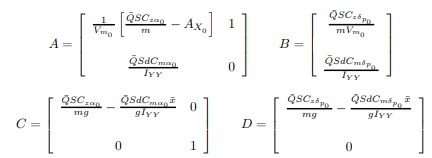

A = [-1.064 1; 290.26 0];
B = [-0.25; -331.4];
C = [-123.34 0; 0 1];
D = [-13.51; 0];

states = {'AoA', 'q'}; 
inputs = {'\delta_c'};
outputs = {'Az', 'q'};

% states = {'Angle of Attack', 'Pitch Rate'}; 
% inputs = {'Control Surface Deflection'};
% outputs = {'Lateral Acceleration', 'Pitch Rate'};

sys = ss(A, B , C, D, 'statename', states, 'inputname', inputs, 'outputname', outputs)


sys =
 
  A = 
           AoA       q
   AoA  -1.064       1
   q     290.3       0
 
  B = 
        \delta_c
   AoA     -0.25
   q      -331.4
 
  C = 
          AoA       q
   Az  -123.3       0
   q        0       1
 
  D = 
       \delta_c
   Az    -13.51
   q          0
 
Continuous-time state-space model.


## Define Transfer Function

tfuncs = tf(sys);
tfunc = tfuncs(2, 1)


tfunc =
 
  From input "\delta_c" to output "q":
    -331.4 s - 425.2
  ---------------------
  s^2 + 1.064 s - 290.3
 
Continuous-time transfer function.
Model Properties


fprintf('The poles of this system are:\n');

The poles of this system are:


disp(pole(tfunc))

  -17.5773
   16.5133



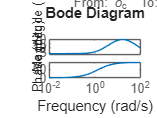

bode(tfunc)

## LQR

LQR Weight Matrices

Q = eye(2)*0.1;
R = 0.5;

LQR Gain

[K, S, e] = lqr(A, B, Q, R);
fprintf('eigenvalues of A-BK\n');

eigenvalues of A-BK


disp(eig(A-B*K));

   -2.5132
 -150.1351



fprintf('Feedback gain K')

Feedback gain K

disp(K)

   -1.4290   -0.4563



## Closed Loop (CL) System

A_cl = A-B*K;
B_cl = B;

sys_cl = ss(A_cl, B_cl, C, D, 'statename', states, 'inputname', inputs, 'outputname', outputs)


sys_cl =
 
  A = 
           AoA       q
   AoA  -1.421  0.8859
   q    -183.3  -151.2
 
  B = 
        \delta_c
   AoA     -0.25
   q      -331.4
 
  C = 
          AoA       q
   Az  -123.3       0
   q        0       1
 
  D = 
       \delta_c
   Az    -13.51
   q          0
 
Continuous-time state-space model.



tfuncs_cl = tf(sys_cl);
tfunc_cl = tfuncs_cl(2, 1)


tfunc_cl =
 
  From input "\delta_c" to output "q":
    -331.4 s - 425.2
  ---------------------
  s^2 + 152.6 s + 377.3
 
Continuous-time transfer function.
Model Properties


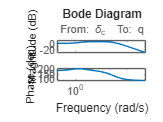

bode(tfunc_cl)

## LQG Kalman Filter Design

G = eye(2);
H = 0*eye(2);

Kalman Q, R Noise Matrices

Qbar = diag(1.5e-4*ones(1, 2));
Rbar = diag(5.5e-1*ones(1, 2));

Define Noisy System

sys_n = ss(A, [B G], C, [D H]);
[k_est, L, P] = kalman(sys_n, Qbar, Rbar, 0);

## Kalman Gain Observer Closed Loop

A_obsv = A-L*C;
% Display Observer Eigenvalues
fprintf('Observer Eigenvalues\n');

Observer Eigenvalues


disp(eig(A_obsv));

  -18.2152
  -15.9376




% Noise Time Constraints
dT1 = 0.75;
dT2 = 0.25;

## Missile Parameters

R = 6371e3; % Earth's Radius
Vel = 1021.08; % Velocity (m/s)
m2f = 3.2811; % Conversion from meters to ft
d2r = pi/180; % Conversion from degrees to radians

% Target Location in Degrees
lat_target = 34.6588;
lon_target = -118.769745;
elev_target = 795; % m - Mean Sea Level (MSL)

% Initial Location in Degrees
lat_init = 34.2329;
lon_init = -119.4573;
elev_init = 1e4; % m - MSL

% Obstacle Location
lat_obs = 34.61916;
lon_obs = -118.8429;

% Convert to Radians
l1 = lat_init*d2r;
u1 = lon_init*d2r;
l2 = lat_target*d2r;
u2 = lon_target*d2r;

% Calculate Distances
dl = l2 - l1;
du = u2 - u1;

## Haversine Formula

The haversine formula determines the great-circle distance between two points on a sphere given their longitudes and latitudes. Important in navigation, it is a special case of a more general formula in spherical trigonometry, the law of haversines, that relates the sides and angles of spherical triangles.

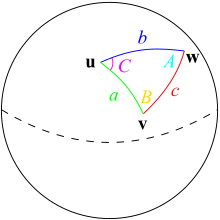

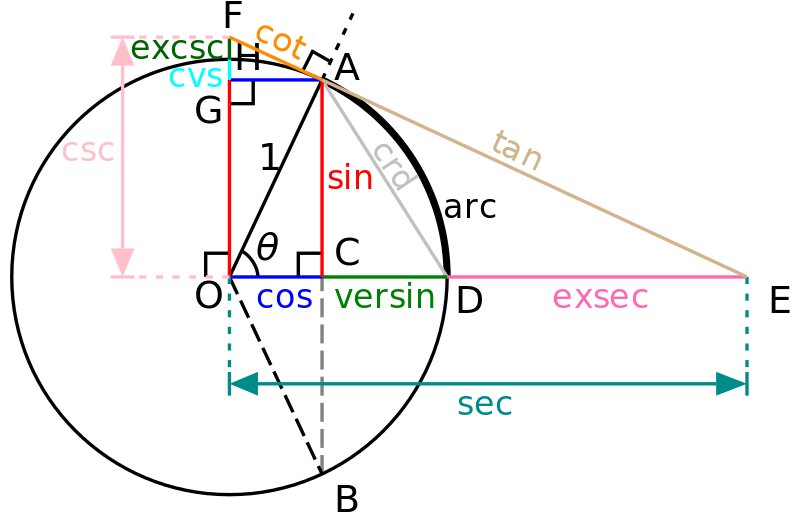

% Haversine Formula
a = sin(dl/2)^2 + cos(l1)*cos(l2)*sin(du/2)^2;
c = 2*atan2(sqrt(a), sqrt(1-a));
d = R*c; % Horizontal Distance (in meters)
r = sqrt(d^2 + (elev_target - elev_init)^2);

% Initial Azimuth (Clock-wise Rotation From North)
yaw_init = azimuth(lat_init, lon_init, lat_target, lon_target);
yaw = yaw_init*d2r;

% Initial Flight Path Angle
dh = abs(elev_target - elev_init);
FPA_init = atan(dh/d)

FPA_init = 0.1162

fprintf("The initial Flight Path Angle in Radians is:")

The initial Flight Path Angle in Radians is:

disp(FPA_init)

    0.1162

